m = 11

m = 11

k = 219

k = 219

W = tf(1/m, [1 0 k/m])

W =
 
    0.09091
  -----------
  s^2 + 19.91
 
Continuous-time transfer function.



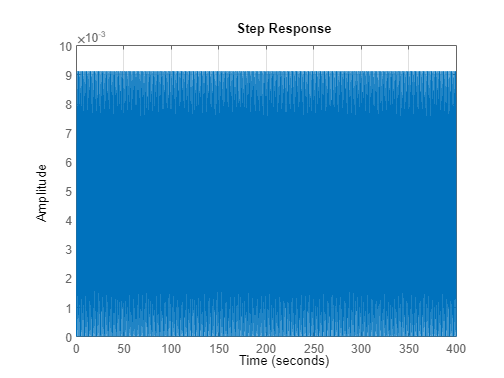

step(W)
% hold on
syms p
grid on

Wp = (1/m) / (p^2 + k/m) / p

$$Wp = \frac{1}{11\,p\,\left(p^{2}+\frac{219}{11}\right)}$$

wp = ilaplace(Wp)

$$wp = \frac{1}{219}-\frac{\cos\left(\frac{\sqrt{11}\,\sqrt{219}\,t}{11}\right)}{219}$$

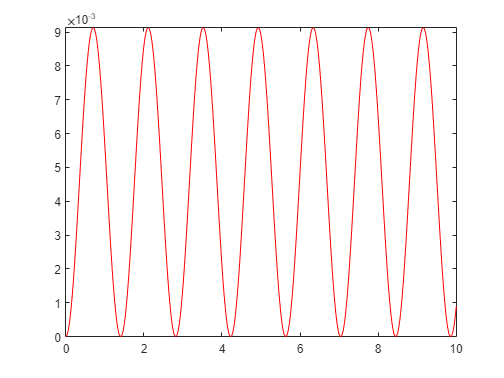

fplot(wp,[0,10],"red")

% syms t
% ir = sin(t*sqrt(k/m))/(sqrt(k*m))
% fplot(ir,[0,10],"red")

% syms p t
% Wp = ( Rl*Ke/L*p ) / (p+ (R+Rl)/L) 
% Wp = ( Rl*Ke/L ) / (p+ (R+Rl)/L)
% w = ilaplace(Wp)
% impulse(W)
% step(W)
% hold on
% grid on
% fplot(w,[0,0.014],"red")



% АЧХ
% syms w
% 
% Wjw = ( 1/m ) / ( -(w)^2 + k/m)
% % A1=sqrt(real(Wjw)^2+imag(Wjw)^2)
% 
% fplot(Wjw,[0,10])
% grid on
% xlabel("Frequency")
% ylabel("Amplitude")
% title("АЧХ")
% legend("A(ω)")
% % фчх
% F=atan2(imag(Wjw), real(Wjw))
% 
% fplot(F,[0,100])
% grid on
% xlabel("Frequency")
% ylabel("Phase")
% title("ФЧХ")
% legend("φ(ω)")
% bode(W)
% grid on